# Propeller Aerodynamic Lookup Table Generator

This interactive document will guide you through the steps necessary to generate a lookup table of aerodynamic values for a propeller calculated with QPROP by MIT. Currently the file will generate thrust and torque tables with inputs of RPM and velocity.

For instructions, theory, and documentation on QPROP, please visit the [MIT QPROP website](https://web.mit.edu/drela/Public/web/qprop/).

This tool is intended to aid the development of aircraft for undergraduate researchers. If any improvements can be made, please contact Tristan Sherman.

## Step 1: Load Propeller Specifications

mprop = 133.333; % grams
mprop = mprop/1000*.0685; % Slugs
prop.MOI = R^2*g*period^2/(4*pi^2*L)*mprop; % slug-ft^2
prop.D = 12/12; % Diameter (ft)

## Step 2: Generate QPROP Geometry File

The QPROP_GeomGen function will convert user specified data into a propeller geometry file in the propgeom folder. To use it, specify the aerodynamic properties in the aero struct, and the geometry values in the geom struct.

**geom.R**: Array of radial stations of the propeller blade

**geom.c**: Array of chord lengths at each radial station

**geom.beta**: Array of geometric twist angles at each radial station

**geom.N**: Number of blades

file.name= 'T28 Trojan Prop'; % Title to be put in first line of geometry file
file.filename = 'T28_Prop';   % Title of geometry file
file.folder = 'propgeom\';    % Folder of geometry file relative to current directory


%% Aerodynamic coefficients from airfoil data
aero.Cla = 4.812;       % Lift curve slope
aero.CL0 = 0.25;        % Lift at 0 deg alpha
aero.CLmin = -0.8;      % Minimum lift
aero.CLmax = 1.3;       % Maximum lift

%% Define drag curve
%   CD(CL,Re)  =  [ CD0 + CD2*(CL-CLCD0)^2 ] * [Re/REref]^REexp
%   where  
%    CD2 = CD2u  if CL > CLCD0
%    CD2 = CD2l  if CL < CLCD0
aero.CD0 = .007;        % Minimum drag
aero.CD2u = 0.015;      % Exponent of drag curve at positive lift
aero.CD2l = 0.006;      % Exponent of drag curve at negative lift
aero.CLCD0 = 0.3634;    % Lift coefficient at minimum drag
aero.REref = 1000000;   % Reference Reynolds number
aero.REexp = -0.5;      % Exponent of Reynolds number (-0.5 is reasonable for most low Re props - per QPROP manual)

% Propeller radius, chords and angles
geom.R = [2, 2.45, 2.7 2.9 3.4 3.7 4.1 4.6 5 5.4 5.7 6]; % in
geom.c = [0.8 0.9 1 1.05 1.09 1.1 1.1 1.1 1.1 1.1 1.1 1.1];  % Chord length (in)
geom.beta = [31 28 21 19 17 16 13 11.5 10 9 8.5 8]; % degrees      
geom.N = 3;
geom.InputLunits = 'inches';

QPROP_GeomGen(geom, aero, file) % Generate QPROP geometry

## Step 3: Define Run Parameters & Generate Data

In this step you will create run parameters to be used with your generated geometry file. This will be done in the following steps.

- Define the input and output file names

- Define your motor file

- Define fluid properties

- Define run parameters

Run parameters define which variables will be used as inputs to the analysis and which will be calculated as outputs. To make a variable an input, define it in the Setpoint class. To define a sweep over an input, define the input as an array where

 To calculate a variable, leave it as an empty array.

%% Input/Output file names
outputfile     = 'runfiles\T28Run_multi';
propfile       = 'propgeom\T28_Prop';

%% Motor file
motorfile      = 'motorfiles\MEGAMOTOR'; % This file removes the motor as a constraint
CurrentLimit   = 1600;     % Maximum current check

%% Define fluid properties in qcon.def file
qcon=[1.225 1.78E-5 340]; % [Density, Viscoity, Speed of Sound}
fileID = fopen('runfiles/qcon.def','w');
fprintf(fileID,'%d \n' ,qcon);
fclose(fileID);
clear fileID qcon

%% Define parameters: Leave empty variables if to be determined
Setpoint.Velocity = [2 44 2];    % Always define
Setpoint.RPM      = [500 30000 500];
Setpoint.Voltage  = [];
Setpoint.dBeta    = 0.0;    % Leave as 0.0
Setpoint.Thrust   = [];
Setpoint.Torque   = [];
Setpoint.Current  = [];
Setpoint.Pele     = [];     % Leave Empty
  
Output = run_qprop(propfile,motorfile,outputfile,Setpoint)

Output = 1320×19 table
    V(m/s)    rpm    Dbeta      T(N)       Q(N-m)      Pshaft(W)    Volts      Amps     effmot     effprop      adv         CT          CP        DV(m/s)      eff      Pelec      Pprop      cl_avg     cd_avg 
    ______    ___    _____    ________    _________    _________    ______    ______    _______    _______    _______    ________    _________    _______    _______    ______

## Step 4: Separate and Visualize Data

Using the Output struct above, separate the data and plot it.

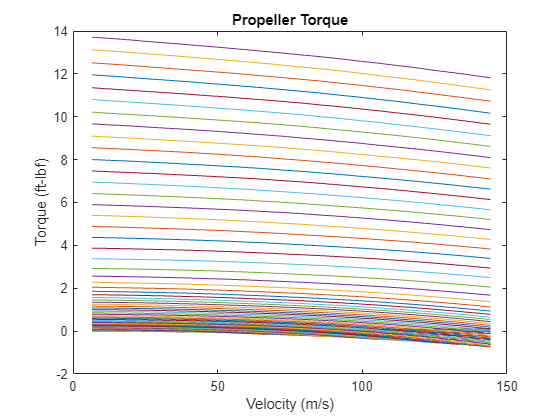

% Find array of unique velocities
vel_array = unique(Output.("V(m/s)"));
n_vel = length(vel_array);

% Find array of unique RPMs
rpm_array = unique(Output.rpm);
n_rpm = length(rpm_array);

% Pull out thrust and torque
Thrust = reshape(Output.("T(N)"),[n_vel,n_rpm])./4.45; % Thrust in lbf
Torque = reshape(Output.("Q(N-m)"),[n_vel,n_rpm])*.73756; %N-m to ft-lbf

plot(vel_array*3.28,Torque)
title("Propeller Torque")
xlabel("Velocity (m/s)")
ylabel("Torque (ft-lbf)")

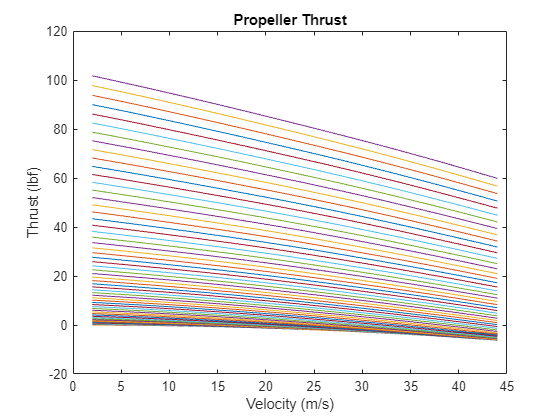

plot(vel_array,Thrust)
title("Propeller Thrust")
xlabel("Velocity (m/s)")
ylabel("Thrust (lbf)")

## (Optional) Create Propeller Data Struct

Use the section below to format your data for export.

prop.Thrust = Thrust;
prop.Torque = Torque;
prop.vel = vel_array'.*3.28;
prop.RPM = rpm_array'

prop = struct with fields:
         D: 1
       MOI: 5.7916e-04
    Thrust: [22×60 double]
    Torque: [22×60 double]
       vel: [6.5600 13.1200 19.6800 26.2400 32.8000 39.3600 45.9200 52.4800 59.0400 65.6000 72.1600 78.7200 85.2800 91.8400 98.4000 104.9600 111.5200 118.0800 124.6400 131.2000 137.7600 144.3200]
       RPM: [500 1000 1500 2000 2500 3000 3500 4000 4500 5000 5500 6000 6500 7000 7500 8000 8500 9000 9500 10000 10500 11000 11500 12000 12500 13000 13500 14000 14500 15000 15500 16000 16500 17000 17500 18000 18500 19000 19500 20000 … ] (1×60 double)


## (Optional) Propeller Airfoil Curve Fitting

You can use the section below to fit the drag curve to your airfoil data from an online database.

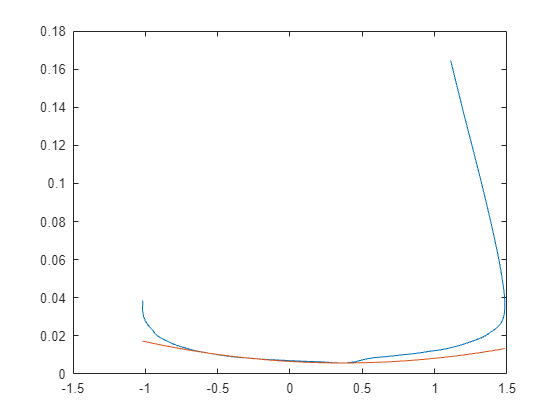

Airfoil = readtable('2408 Airfoil Data.txt');
CL = Airfoil.CL;
CD = Airfoil.CD;

% First fit CD2 to the CD curve for CL > 0 to find CD2u.
% Second, fit CD2 to the CD curve for CL < 0 to find CD2l.
CD0 = 0.0058;       % Profile drag from data
CLCD0 = 0.3634;     % CL at minimum drag from data
CD2 = 0.006;        % Curve fit tester

plot(CL,CD)
hold on
plot(CL, CD0+CD2.*(CL- CLCD0).^2) % Plot estimated drag curve
hold off

## References

- https://web.mit.edu/drela/Public/web/qprop/

- https://web.mit.edu/drela/Public/web/qprop/qprop_doc.txt